The `spheroidal` library allows users to 

spheroid_system = SpheroidalParameters;
spheroid_system

spheroid_system =   SpheroidalParameters with properties:

                 sigma: []
    sigma_coefficients: []
                    u0: []
                     a: []
               centers: [0 0 0]
                thetas: 0
                  phis: 0
                isReal: 0
            matvec_eta: []
                     p: 0


We can adjust the shape and size of spheroids by setting the parameters `a` and `u0`. A prolate spheroid will have a semimajor axis of `a*u0` and semiminor axis of `a*sqrt(u0^2-1)`. 

SpheroidalParameters object was not assigned an order, p.
Using a default of p=8 to generate coordinates.


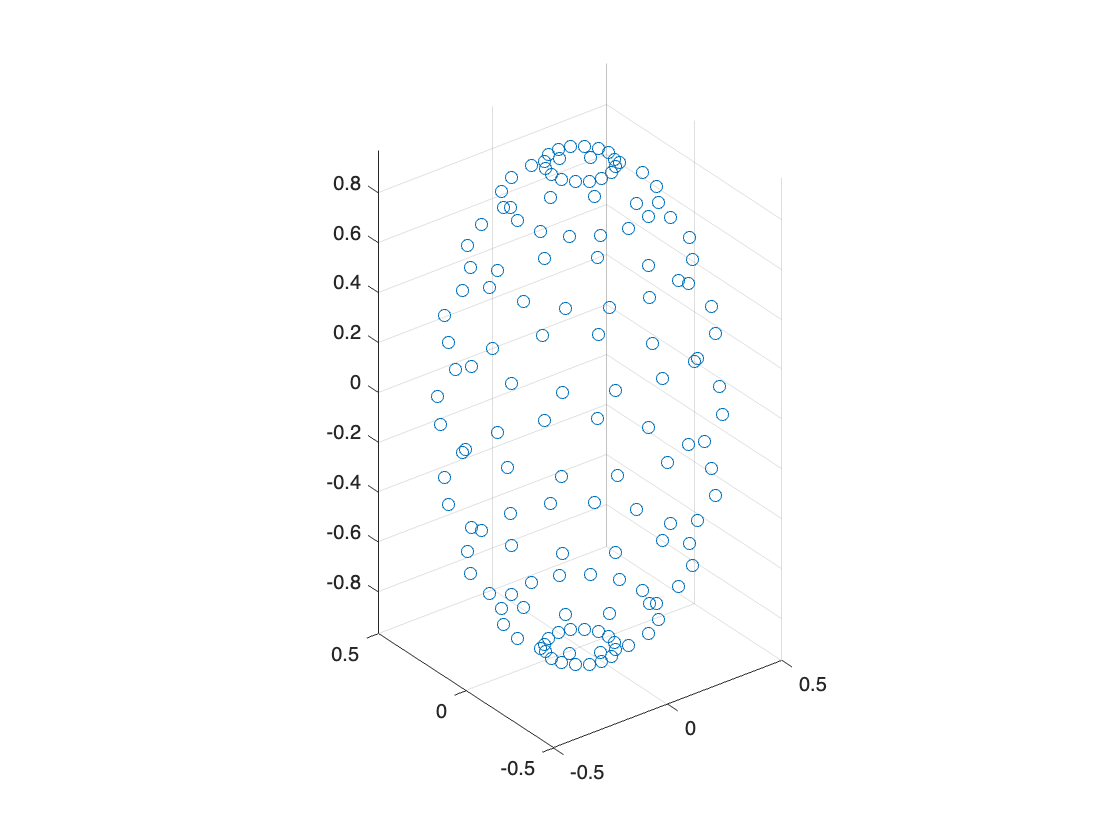

spheroid_system.u0 = 2/sqrt(3);
spheroid_system.a = sqrt(3)/2;
spheroid_system.plot;

The columns of `sigma` are the density functions on each spheroid in the system

[theta, phi] = gl_grid(8);
sigma1 = cos(theta);
sigma2 = sin(theta).*sin(phi);
spheroid_system.sigma = [sigma1 sigma2];
spheroid_system

spheroid_system =   SpheroidalParameters with properties:

                 sigma: [144×2 double]
    sigma_coefficients: []
                    u0: 1.1547
                     a: 0.8660
               centers: [0 0 0]
                thetas: 0
                  phis: 0
                isReal: 0
            matvec_eta: []
                     p: 8
